Plot original Runge's function

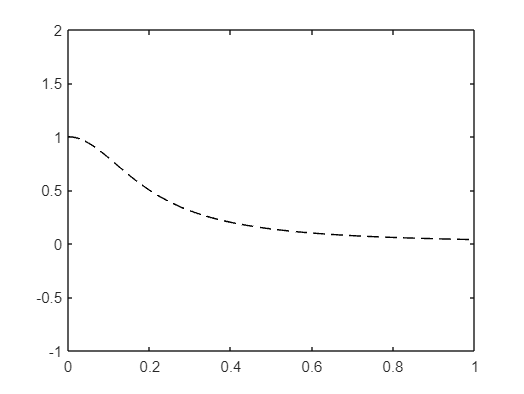

xx = 0 : 0.01 : 1;
yy = 1 ./ (1+25.*xx.^2);
plot(xx, yy, 'k--')
axis([0 1 -1 2])


xtest = 0.6;
true = 1 ./ (1+25.*xtest.^2)

true = 0.1000

Fit with 2th-order polynomial

x = linspace(0, 1, 3);
y = 1 ./ (1+25.*(x.^2));
p2 = polyfit(x, y, 2)

p2 =     1.5252   -2.4867    1.0000


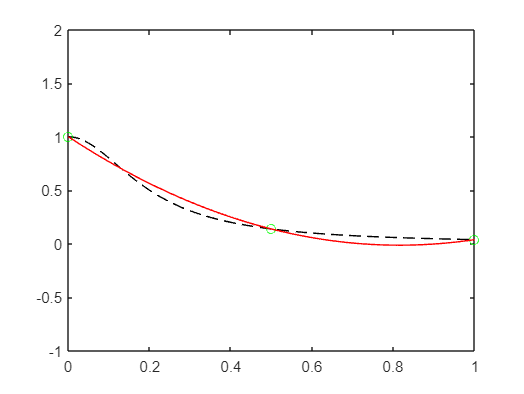

yy2 = polyval(p2, xx);

plot(xx, yy, 'k--')
hold on
plot(x, y, 'og')
hold on
plot(xx, yy2, 'r-')
hold off

axis([0 1 -1 2])

xtest = 0.6;
y_pred = polyval(p2,xtest)

y_pred = 0.0570

error = abs(((true - y_pred)/true)*100)

error = 42.9708

Fit with 3th-order polynomial

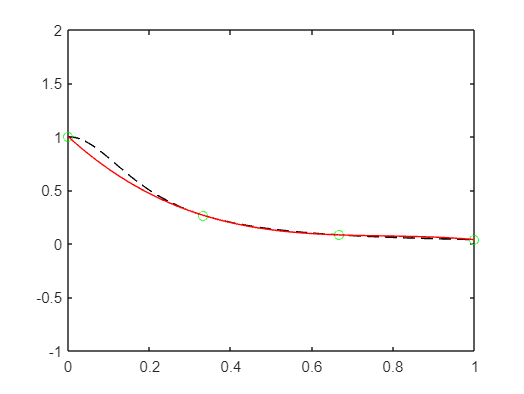

x = linspace(0, 1, 4);
y = 1 ./ (1+25.*(x.^2));
p3 = polyfit(x, y, 3);
yy3 = polyval(p3, xx);

plot(xx, yy, 'k--')
hold on
plot(x, y, 'og')
hold on
plot(xx, yy3, 'r-')
hold off

axis([0 1 -1 2])

xtest = 0.6;
y_pred = polyval(p3,xtest)

y_pred = 0.0947

error = abs(((true - y_pred)/true)*100)

error = 5.3302

Fit with 4th-order polynomial

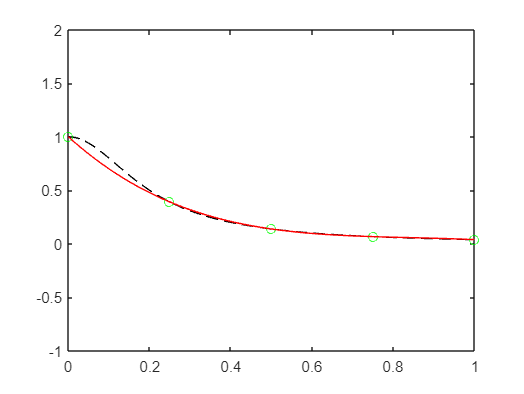

x = linspace(0, 1, 5);
y = 1 ./ (1+25.*(x.^2));
p4= polyfit(x, y, 4);
yy4 = polyval(p4, xx);

plot(xx, yy, 'k--')
hold on
plot(x, y, 'og')
hold on
plot(xx, yy4, 'r-')
hold off

axis([0 1 -1 2])

xtest = 0.6;
y_pred = polyval(p4,xtest)

y_pred = 0.0962

error = abs(((true - y_pred)/true)*100)

error = 3.8120

Assume that we have 5 data points from this Runge's function at x = 0.00,  0.25,  0.50,  0.75,  1.00

When y = 0.5, find the correct value of x analytically

x = [0.00 0.25 0.50 0.75 1.00];
y = 1 ./ (1+25.*x.^2);
p4= polyfit(x, y, 4)

p4 =     0.4215   -2.5167    4.5627   -3.4290    1.0000



yy4 = polyval(p4, xx)

yy4 =     1.0000    0.9662    0.9332    0.9012    0.8700    0.8396    0.8101    0.7815    0.7536    0.7265    0.7003    0.6747    0.6500    0.6259    0.6026    0.5800    0.5581    0.5369    0.5164    0.4965    0.4773    0.4586    0.4406    0.4233    0.4065    0.3902    0.3746    0.3595    0.3449    0.3309    0.3174    0.3044    0.2919    0.2799    0.2683    0.2572    0.2465    0.2363    0.2265    0.2171    0.2082    0.1996    0.1913    0.1835    0.1760    0.1688    0.1620    0.1555    0.1494    0.1435



plot(xx, yy, 'k--')
hold on
plot(x, y, 'og')
hold on
plot(xx, yy4, 'r-')
hold off

axis([0 1 -1 2])

xtest = 0.6;
y_pred = polyval(p4,xtest)

y_pred = 0.0962

error = abs(((true - y_pred)/true)*100)

error = 3.8120

Now assume that we don't know the Runge's function.  Using quadratic interpolation and the quadratic formula to determine the value of x numerically. (use the first three points to fit quadratic polynomial)